% linear convolution
% circular convolution
% dft , idft
% power spectral density
% -Two sided
% -One sided
% DTMF
% butterworth IIR
% -LPF
% -HPF
% -BPF
% -BSF
%interpolation and decimation
%sinusoidal signal generation
%
clc
clear all
close all
x=input('enter x: ')

x =      1     2     3     4


h=input('enter h: ')

h =      2     1     2     1


N=length(x)

N = 4

M=length(h)

M = 4

l=N+M-1

l = 7

y=zeros(1,l)

y =      0     0     0     0     0     0     0


for n=1:l
    y(n)=0
    for k=max(n-M+1,1):min(n,N)
        y(n)=y(n)+x(n-k+1)*h(k)
    end
end

y =      2     0     0     0     0     0     0


y =      2     4     0     0     0     0     0


y =      2     5     0     0     0     0     0


y =      2     5     6     0     0     0     0


y =      2     5     8     0     0     0     0


y =      2     5    10     0     0     0     0


y =      2     5    10     8     0     0     0


y =      2     5    10    11     0     0     0


y =      2     5    10    15     0     0     0


y =      2     5    10    16     0     0     0


y =      2     5    10    16     4     0     0


y =      2     5    10    16    10     0     0


y =      2     5    10    16    12     0     0


y =      2     5    10    16    12     8     0


y =      2     5    10    16    12    11     0


y =      2     5    10    16    12    11     4


z=conv(x,h)

z =      2     5    10    16    12    11     4


lc=ifft(fft(x,l).*fft(h,l))

lc =     2.0000    5.0000   10.0000   16.0000   12.0000   11.0000    4.0000


clc
clear all
close all
x=input('enter x')

x =      1     2     3     4


h=input('enter h')

h =      2     1     2     1


l=max(length(x),length(h))

l = 4

N=length(x)

N = 4

M=length(h)

M = 4

y=zeros(1,l)

y =      0     0     0     0


x=[x zeros(l-N)]

x =      1     2     3     4


h=[h zeros(l-M)]

h =      2     1     2     1


for n=1:l
    y(n)=0
    for k=1:l
        id=mod(n-k,N)+1
        y(n)=y(n)+x(id)*h(k)
    end
end

y =      0     0     0     0


id = 1

y =      2     0     0     0


id = 4

y =      6     0     0     0


id = 3

y =     12     0     0     0


id = 2

y =     14     0     0     0


y =     14     0     0     0


id = 2

y =     14     4     0     0


id = 1

y =     14     5     0     0


id = 4

y =     14    13     0     0


id = 3

y =     14    16     0     0


y =     14    16     0     0


id = 3

y =     14    16     6     0


id = 2

y =     14    16     8     0


id = 1

y =     14    16    10     0


id = 4

y =     14    16    14     0


y =     14    16    14     0


id = 4

y =     14    16    14     8


id = 3

y =     14    16    14    11


id = 2

y =     14    16    14    15


id = 1

y =     14    16    14    16


cc=cconv(x,h,l)

cc =     14    16    14    16


z=ifft(fft(x).*fft(h))

z =     14    16    14    16


%dft
clc
clear all
close all
x=input('enter x: ')

x =      1     2     3     4


N=length(x)

N = 4

y=zeros(N,1)

y =      0
     0
     0
     0


for n=0:N-1
    for k=0:N-1
        y(n+1)=y(n+1)+x(k+1)*exp(-1*1i*2*pi*n*k/N)
    end
end

y =      1
     0
     0
     0


y =      3
     0
     0
     0


y =      6
     0
     0
     0


y =     10
     0
     0
     0


y =     10
     1
     0
     0


y =   10.0000 + 0.0000i
   1.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   1.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -1.0000 - 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   2.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   1.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   1.0000 + 2.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 + 2.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 - 2.0000i


z=fft(x)

z =   10.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 + 0.0000i  -2.0000 - 2.0000i


%idft
clc
clear all
close all
x=input('enter x: ')

x =      1     2     3     4


N=length(x)

N = 4

y=zeros(N,1)

y =      0
     0
     0
     0


for n=0:N-1
    for k=0:N-1
        y(n+1)=y(n+1)+x(k+1)*exp(1i*2*pi*n*k/N)
    end
    y(n+1)=y(n+1)/N
end

y =      1
     0
     0
     0


y =      3
     0
     0
     0


y =      6
     0
     0
     0


y =     10
     0
     0
     0


y =     2.5000
         0
         0
         0


y =     2.5000
    1.0000
         0
         0


y =    2.5000 + 0.0000i
   1.0000 + 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -2.0000 + 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -2.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
   1.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -1.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
   2.0000 - 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -2.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
   1.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
   1.0000 - 2.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
  -2.0000 - 2.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
  -2.0000 + 2.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
  -0.5000 + 0.5000i


z=ifft(x)

z =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i  -0.5000 + 0.5000i


%power spectral density two sides
clc
clear all
close all
fs=10000

fs = 10000

f1=500

f1 = 500

f2=2000

f2 = 2000

N=200

N = 200

t=0:N-1

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=sin(2*pi*f1*t/fs)+2*sin(2*pi*f2*t/fs)

x =          0    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931   -0.0000    1.5931    0.5878   -1.9846   -2.8532   -1.0000    0.9511    0.3666   -1.7634   -2.2111   -0.0000    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931   -0.0000    1.5931    0.5878   -1.9846   -2.8532   -1.0000    0.9511    0.3666   -1.7634   -2.2111   -0.0000    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931


xf=2*abs(fft(x))/N

xf =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


two_power=xf.*xf

two_power =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    4.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


f=(0:N-1)*fs/N

f =            0          50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400        1450        1500        1550        1600        1650        1700        1750        1800        1850        1900        1950        2000        2050        2100        2150        2200        2250        2300        2350        2400        2450


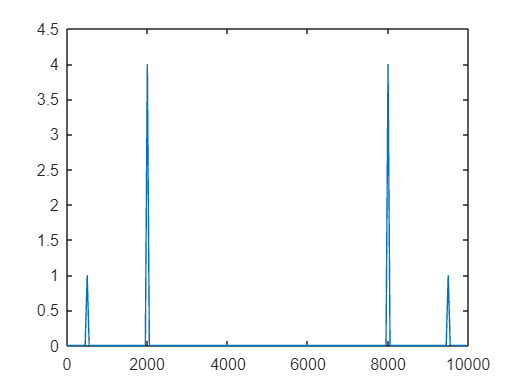

plot(f,two_power)

%power spectral density one sided
clc
clear all
close all
fs=10000

fs = 10000

f1=500

f1 = 500

f2=2000

f2 = 2000

N=200

N = 200

t=0:N-1

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=sin(2*pi*f1*t/fs)+2*sin(2*pi*f2*t/fs)

x =          0    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931   -0.0000    1.5931    0.5878   -1.9846   -2.8532   -1.0000    0.9511    0.3666   -1.7634   -2.2111   -0.0000    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931   -0.0000    1.5931    0.5878   -1.9846   -2.8532   -1.0000    0.9511    0.3666   -1.7634   -2.2111   -0.0000    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931


xf=abs(fft(x))/N

xf =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.5000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


u=2*xf

u =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


one_side=u.*u

one_side =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    4.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


f=(0:(N-1)/2+1)*fs/N

f =            0          50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400        1450        1500        1550        1600        1650        1700        1750        1800        1850        1900        1950        2000        2050        2100        2150        2200        2250        2300        2350        2400        2450


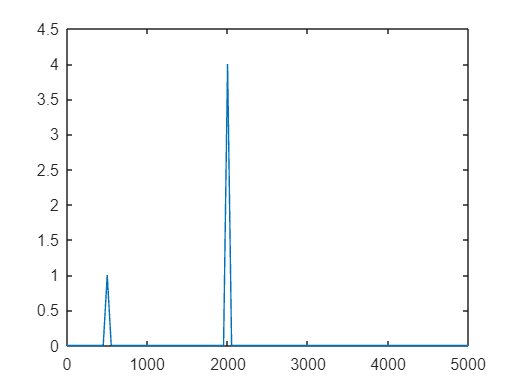

plot(f,one_side(1:(N/2+1)))

%DTMF
clc
clear all
close all
dtmf_fq=[
    941,1336;%0
    697,1209;%1
    697,1336;%2
    770,1209;%3
    770,1336;%4
    770,1477;%5
    852,1209;%6
    852,1336;%7
    852,1477;%8
    941,1336;%9
    ]

dtmf_fq =          941        1336
         697        1209
         697        1336
         770        1209
         770        1336
         770        1477
         852        1209
         852        1336
         852        1477
         941        1336


digit=input('enter a digit (0-9) : ')

digit = 2

fs = 44100

duration = 0.5000

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


tone1 =          0    0.0991    0.1973    0.2935    0.3869    0.4764    0.5612    0.6405    0.7135    0.7794    0.8377    0.8877    0.9290    0.9611    0.9838    0.9967    0.9998    0.9931    0.9766    0.9505    0.9150    0.8705    0.8174    0.7562    0.6877    0.6123    0.5309    0.4443    0.3532    0.2588    0.1617    0.0631   -0.0362   -0.1351   -0.2326   -0.3279   -0.4200   -0.5079   -0.5908   -0.6679   -0.7384   -0.8016   -0.8569   -0.9038   -0.9418   -0.9705   -0.9896   -0.9990   -0.9985   -0.9882


tone2 =          0    0.1892    0.3716    0.5405    0.6899    0.8144    0.9095    0.9717    0.9988    0.9899    0.9452    0.8663    0.7562    0.6187    0.4589    0.2825    0.0959   -0.0942   -0.2808   -0.4574   -0.6173   -0.7550   -0.8655   -0.9446   -0.9896   -0.9989   -0.9721   -0.9102   -0.8154   -0.6912   -0.5419   -0.3732   -0.1909   -0.0017    0.1875    0.3700    0.5391    0.6887    0.8134    0.9088    0.9713    0.9988    0.9901    0.9457    0.8672    0.7573    0.6200    0.4604    0.2841    0.0976


tone =          0    0.2883    0.5689    0.8340    1.0768    1.2908    1.4707    1.6122    1.7123    1.7693    1.7829    1.7540    1.6851    1.5798    1.4426    1.2792    1.0957    0.8989    0.6958    0.4931    0.2976    0.1154   -0.0481   -0.1884   -0.3020   -0.3866   -0.4412   -0.4660   -0.4622   -0.4324   -0.3802   -0.3101   -0.2271   -0.1368   -0.0451    0.0421    0.1191    0.1808    0.2227    0.2409    0.2330    0.1972    0.1332    0.0419   -0.0746   -0.2132   -0.3696   -0.5386   -0.7144   -0.8906


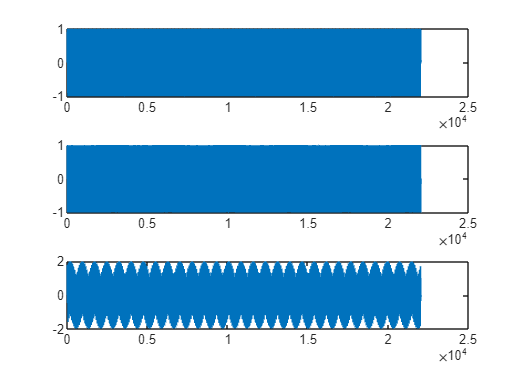

if digit>=0 && digit<=9
    fs=44100
    duration =0.5
    t=0:1/fs:duration
    tone1=sin(2*pi*dtmf_fq(digit+1,1)*t)
    tone2=sin(2*pi*dtmf_fq(digit+1,2)*t)
    tone=tone1+tone2
    sound(tone,fs)
    subplot(3,1,1)
    plot(tone1)
    subplot(3,1,2)
    plot(tone2)
    subplot(3,1,3)
    plot(tone)
else
    disp('invalid')
end

%butterworth iir LPF
clc
clear all
close all
wp=input('enter pass band cutoff frequency: ')

wp = 1000

ws=input('enter stop band cutoff frequency: ')

ws = 3000

deltap=input('enter pass band ripple: ')

deltap = 3

deltas=input('enter stopband ripple: ')

deltas = 4

fs=10000

fs = 10000

omegap=2*tan(2*wp/fs)/sqrt(1+tan(2*wp/fs)^2)

omegap = 0.3973

omegas=2*tan(2*ws/fs)/sqrt(1+tan(2*ws/fs)^2)

omegas = 1.1293

num=log10(omegas/omegap)

num = 0.4536

delta=min(1/deltap^2-1,1/deltas^2-1)

delta = -0.9375

del=1/deltap^2-1

del = -0.8889

den=2*log10(delta/del)

den = 0.0462

fc=1000

fc = 1000

order=ceil(num/den)

order = 10

fc=1000

fc = 1000

[b,a]=butter(order,fc/(fs/2),"low")

b = 1.0e-03 *

    0.0017    0.0168    0.0758    0.2020    0.3536    0.4243    0.3536    0.2020    0.0758    0.0168    0.0017


a =     1.0000   -5.9876   16.6722  -28.2588   32.1598  -25.6017   14.4057   -5.6471    1.4737   -0.2309    0.0165


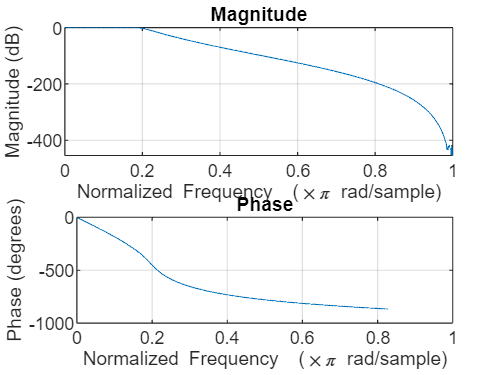

freqz(b,a,1000)

%HPF butterworth IIR
clc
clear all
close all
wp=input('enter pass band cutoff freq: ')

wp = 1000

ws=input('enter stop band cutoff freq: ')

ws = 2000

deltap=input('enter pass abnd ripple: ')

deltap = 3

deltas=input('enter stopband ripple: ')

deltas = 4

fs=10000

fs = 10000

omegap=2*tan(2*wp/fs)/sqrt(1+tan(2*wp/fs)^2)

omegap = 0.3973

omegas=2*tan(2*ws/fs)/sqrt(1+tan(2*ws/fs)^2)

omegas = 0.7788

den=log10(omegas/omegap)

den = 0.2923

delta=min(1/deltap^2-1,1/deltas^2-1)

delta = -0.9375

del=1/deltap^2-1

del = -0.8889

num=2*log10(delta/del)

num = 0.0462

order=ceil(num/den)

order = 1

fc=1000

fc = 1000

[b,a]=butter(order,fc/(fs/2),'high')

b =     0.7548   -0.7548


a =     1.0000   -0.5095


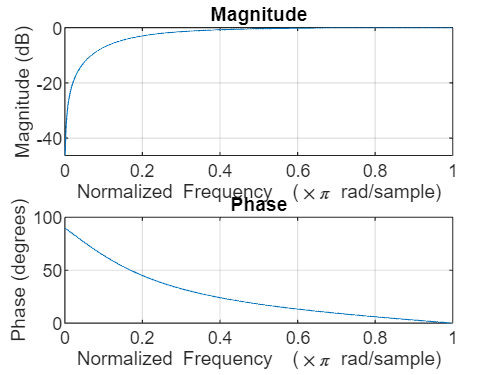

freqz(b,a,1000)

%butterworth BandPass IIR
clc
clear all
close all
wp=input('enter pass band freq: ')

wp = 1000

ws=input('enter stop band freq: ')

ws = 3000

deltap=input('enter pass band ripple: ')

deltap = 3

deltas=input('enter stopband ripple: ')

deltas = 4

wp1=input('enter pass band freq1: ')

wp1 = 6000

ws1=input('enter stop band freq-1: ')

ws1 = 8000

fs=10000

fs = 10000

omegap1=2*tan(2*wp/fs)/sqrt(1+tan(2*wp/fs)^2)

omegap1 = 0.3973

omegas1=2*tan(2*ws/fs)/sqrt(1+tan(2*ws/fs)^2)

omegas1 = 1.1293

omegap2=2*tan(2*wp1/fs)/sqrt(1+tan(2*wp1/fs)^2)

omegap2 = 1.8641

omegas2=2*tan(2*ws1/fs)/sqrt(1+tan(2*ws1/fs)^2)

omegas2 = -1.9991

den=log10(omegas1*omegas2/omegap1*omegap2)

den = 1.0250 + 1.3644i

delta=min(1/deltap^2-1,1/deltas^2-1)

delta = -0.9375

del=1/deltap^2-1

del = -0.8889

num=2*log10(delta/del)

num = 0.0462

order=ceil(num/den)

order = 1

fc=1000

fc = 1000

[b,a]=butter(order,[fc/(fs/2),fc/(fs/2)+0.1],'bandpass')

b =     0.1367         0   -0.1367


a =     1.0000   -1.2361    0.7265


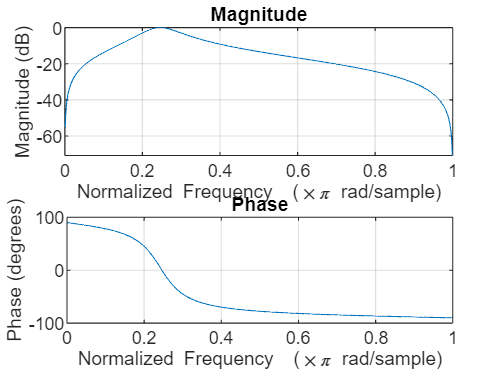

freqz(b,a,1000)

%butterworth BandStop IIR
clc
clear all
close all
wp=input('enter pass band frequency: ')

wp = 3000

ws=input('enter stop band frequency: ')

ws = 4000

wp1=input('enter pass band freq-1: ')

wp1 = 5000

ws1=input('enter stop band freq-1: ')

ws1 = 7000

deltap=input('enter pass abnd ripple: ')

deltap = 4

deltas=input('enter stopband ripple: ')

deltas = 7

fs=10000

fs = 10000

omegap=2*tan(2*wp/fs)/sqrt(1+tan(2*wp/fs)^2)

omegap = 1.1293

omegas=2*tan(2*ws/fs)/sqrt(1+tan(2*ws/fs)^2)

omegas = 1.4347

omegap1=2*tan(2*wp1/fs)/sqrt(1+tan(2*wp1/fs)^2)

omegap1 = 1.6829

omegas1=2*tan(2*ws1/fs)/sqrt(1+tan(2*ws1/fs)^2)

omegas1 = 1.9709

den=log10(omegas*omegas1/omegap1*omegap)

den = 0.2782

delta=min(1/deltap^2-1,1/deltas^2-1)

delta = -0.9796

del=1/deltap^2-1

del = -0.9375

num=2*log10(delta/del)

num = 0.0381

order=ceil(num/den)

order = 1

fc=1000

fc = 1000

[b,a]=butter(order,[fc/(fs/2),fc/(fs/2)+0.1],'stop')

b =     0.8633   -1.2361    0.8633


a =     1.0000   -1.2361    0.7265


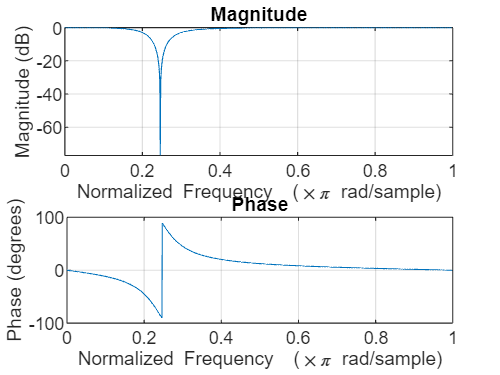

freqz(b,a,1000)

%chebyshev LPF IIR
clc
clear all
close all
wp=input('enter pass band freq: ')
ws=input('enter stop band freq: ')
deltap=input('enter pass band ripple: ')
deltas=input('enter stop band ripple: ')
fs=10000
omegap=(2/fs)*tan(wp/2)
omegas=(2/fs)*tan(ws/2)
den=log10(omegas/omegap)
del=1/deltap^2-1
delta=1/deltas^2-1
num=2*log10(delta/del)
order=ceil(num/den)
re=-20*log10(1/deltap)
fc=1000
[b,a]=cheby1(order,re,fc/(fs/2),'low')
freqz(b,a,1000,fs)

%chebyshev HPF IIR
clc
clear all
close all
wp=input('enter pass band freq: ')
ws=input('enter stop band freq: ')
deltap=input('enter pass band ripple: ')
deltas=input('enter stop band ripple: ')
fs=10000
fc=1000
omegap=2/fs*tan(wp/2)
omegas=2/fs*tan(ws/2)
delta=(1/deltas^2-1)
del=1/deltap^2-1
num=2*log10(delta/del)
den=log10(omegas/omegap)
order=ceil(num/den)
re=-20*log(1/deltap)
[b,a]=cheby1(order,re,fc/(fs/2),'high')
freqz(b,a,1000,fs)

% Chebyshev BPF IIR
clc
clear all
close all

wp = input('Enter pass band freq: ');
ws = input('Enter stop band freq: ');
deltap = input('Enter pass band ripple: ');
deltas = input('Enter stop band ripple: ');
wp1 = input('Enter pass band freq-1: ');
ws1 = input('Enter stop band freq-1: ');
fs = 10000;
fc = 1000;

omegap = 2/fs * tan(wp/2);
omegas = 2/fs * tan(ws/2);
omegap1 = 2/fs * tan(wp1/2);
omegas1 = 2/fs * tan(ws1/2);
delta = 1/deltas^2 - 1;
del = 1/deltap^2 - 1;
num = 2 * log10(delta/del);
den = log10(omegas*omegas1/(omegap*omegap1));
re = -20 * log10(1/deltap);
order = ceil(num/den);
order=1
[b, a] = cheby1(order, re, [0.1, 0.2], 'bandpass');

freqz(b, a, 1000, fs);


%chebyshev BSF IIR
clc
clear all
close all
wp=input('enter pass band freq: ')
ws=input('enter stop band freq: ')
deltap=input('enter pass band riple: ')
deltas=input('enter stop band ripple: ')
wp1=input('enter pass band freq-1: ')
ws1=input('enter stop band freq-1: ')
fs=10000
fc=1000
omegap=2/fs*tan(wp/2)
omegas=2/fs*tan(ws/2)
omegap1=2/fs*tan(wp1/2)
omegas1=2/fs*tan(ws1/2)
den=log10(omegas*omegas1/omegap*omegap1)
delta=1/deltas^2-1
del=1/deltas^2-1
num=2*log10(delta/del)
order=ceil(num/den)
re=-20*log10(1/deltap)
order=1
[b,a]=cheby1(order,re,[0.1,0.2],'stop')
freqz(b,a,fc,fs)

%decimation
clc
clear all
close all
d=input('enter decimation factor: ')

d = 2

N=input('enter number of samples: ')

N = 200

u=0:N-1

u =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=sin(2*pi*0.46*u)+2*sin(2*pi*0.36*u)

x =          0    1.7897   -2.4463    1.6481   -0.1081   -0.9511    0.6906    0.7316   -2.2739    2.7666   -1.7634   -0.1293    1.6843   -1.9350    0.8655    0.5878   -1.2255    0.4643    1.2330   -2.6867    2.8532   -1.5806   -0.2790    1.4828   -1.2923    0.0000    1.2923   -1.4828    0.2790    1.5806   -2.8532    2.6867   -1.2330   -0.4643    1.2255   -0.5878   -0.8655    1.9350   -1.6843    0.1293    1.7634   -2.7666    2.2739   -0.7316   -0.6906    0.9511    0.1081   -1.6481    2.4463   -1.7897


subplot(2,1,1)
stem(u,x)
i=1

i = 1

w=1

w = 1

l=(N/d)

l = 100

c=zeros(1,l-1)

c =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i=1:l
    y(i)=x(w)
    w=w+d
end

y = 0

w = 3

y =          0   -2.4463


w = 5

y =          0   -2.4463   -0.1081


w = 7

y =          0   -2.4463   -0.1081    0.6906


w = 9

y =          0   -2.4463   -0.1081    0.6906   -2.2739


w = 11

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634


w = 13

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843


w = 15

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655


w = 17

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255


w = 19

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330


w = 21

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532


w = 23

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790


w = 25

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923


w = 27

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923


w = 29

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790


w = 31

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532


w = 33

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330


w = 35

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255


w = 37

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655


w = 39

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843


w = 41

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634


w = 43

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739


w = 45

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906


w = 47

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081


w = 49

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463


w = 51

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000


w = 53

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463


w = 55

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081


w = 57

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906


w = 59

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 61

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634


w = 63

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843


w = 65

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655


w = 67

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255


w = 69

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330


w = 71

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532


w = 73

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790


w = 75

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923


w = 77

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923


w = 79

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790


w = 81

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532


w = 83

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330


w = 85

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255


w = 87

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655


w = 89

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843


w = 91

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634


w = 93

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739


w = 95

y =          0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906


w = 97

y = 1×49
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 99

y = 1×50
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 101

y = 1×51
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 103

y = 1×52
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 105

y = 1×53
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 107

y = 1×54
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 109

y = 1×55
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 111

y = 1×56
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 113

y = 1×57
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 115

y = 1×58
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 117

y = 1×59
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 119

y = 1×60
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 121

y = 1×61
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 123

y = 1×62
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 125

y = 1×63
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 127

y = 1×64
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 129

y = 1×65
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 131

y = 1×66
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 133

y = 1×67
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 135

y = 1×68
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 137

y = 1×69
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 139

y = 1×70
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 141

y = 1×71
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 143

y = 1×72
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 145

y = 1×73
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 147

y = 1×74
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 149

y = 1×75
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 151

y = 1×76
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 153

y = 1×77
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 155

y = 1×78
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 157

y = 1×79
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 159

y = 1×80
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 161

y = 1×81
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 163

y = 1×82
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 165

y = 1×83
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 167

y = 1×84
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 169

y = 1×85
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 171

y = 1×86
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 173

y = 1×87
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 175

y = 1×88
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 177

y = 1×89
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 179

y = 1×90
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 181

y = 1×91
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 183

y = 1×92
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 185

y = 1×93
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 187

y = 1×94
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 189

y = 1×95
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 191

y = 1×96
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 193

y = 1×97
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 195

y = 1×98
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 197

y = 1×99
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 199

y = 1×100
         0   -2.4463   -0.1081    0.6906   -2.2739   -1.7634    1.6843    0.8655   -1.2255    1.2330    2.8532   -0.2790   -1.2923    1.2923    0.2790   -2.8532   -1.2330    1.2255   -0.8655   -1.6843    1.7634    2.2739   -0.6906    0.1081    2.4463   -0.0000   -2.4463   -0.1081    0.6906   -2.2739


w = 201

v=0:l-1

v = 1×100
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29


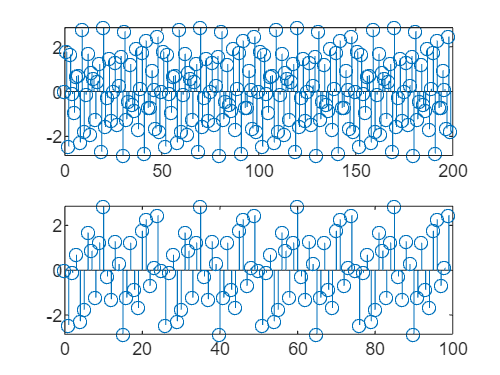

subplot(2,1,2)
stem(v,y)

%interpolation
clc
clear all
close all
N=input('enter number of samples: ')

N = 200

I=input('enter interpolation factor: ')

I = 2

u=0:N-1

u =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=sin(2*pi*0.4*u)+2*sin(2*pi*0.3*u)

x =          0    2.4899   -2.1266   -0.2245    1.3143    0.0000   -1.3143    0.2245    2.1266   -2.4899   -0.0000    2.4899   -2.1266   -0.2245    1.3143    0.0000   -1.3143    0.2245    2.1266   -2.4899   -0.0000    2.4899   -2.1266   -0.2245    1.3143    0.0000   -1.3143    0.2245    2.1266   -2.4899   -0.0000    2.4899   -2.1266   -0.2245    1.3143   -0.0000   -1.3143    0.2245    2.1266   -2.4899   -0.0000    2.4899   -2.1266   -0.2245    1.3143    0.0000   -1.3143    0.2245    2.1266   -2.4899


subplot(2,1,1)
stem(u,x)
l=(N*I)-1

l = 399

y=zeros(1,l)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i=1

i = 1

w=1

w = 1

for i=1:N
    y(w)=x(i)
    w=w+I
end

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


w = 3

y =          0         0    2.4899         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 5

y =          0         0    2.4899         0   -2.1266         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 7

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 9

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 11

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 13

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 15

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 17

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 19

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 21

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 23

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 25

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 27

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 29

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 31

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 33

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 35

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 37

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0         0         0         0         0         0         0         0         0         0         0         0         0


w = 39

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0         0         0         0         0         0         0         0         0         0         0


w = 41

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0         0         0         0         0         0         0         0         0


w = 43

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0         0         0         0         0         0         0


w = 45

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0         0         0         0         0


w = 47

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0         0         0


w = 49

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 51

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 53

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 55

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 57

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 59

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 61

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 63

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 65

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 67

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 69

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 71

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 73

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 75

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 77

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 79

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 81

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 83

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 85

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 87

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 89

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 91

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 93

y =          0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 95

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 97

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 99

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 101

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 103

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 105

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 107

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 109

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 111

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 113

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 115

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 117

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 119

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 121

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 123

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 125

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 127

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 129

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 131

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 133

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 135

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 137

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 139

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 141

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 143

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 145

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 147

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 149

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 151

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 153

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 155

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 157

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 159

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 161

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 163

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 165

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 167

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 169

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 171

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 173

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 175

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 177

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 179

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 181

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 183

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 185

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 187

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 189

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 191

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 193

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 195

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 197

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 199

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 201

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 203

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 205

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 207

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 209

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 211

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 213

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 215

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 217

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 219

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 221

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 223

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 225

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 227

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 229

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 231

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 233

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 235

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 237

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 239

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 241

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 243

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 245

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 247

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 249

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 251

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 253

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 255

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 257

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 259

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 261

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 263

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 265

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 267

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 269

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 271

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 273

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 275

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 277

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 279

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 281

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 283

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 285

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 287

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 289

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 291

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 293

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 295

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 297

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 299

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 301

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 303

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 305

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 307

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 309

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 311

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 313

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 315

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 317

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 319

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 321

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 323

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 325

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 327

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 329

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 331

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 333

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 335

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 337

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 339

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 341

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 343

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 345

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 347

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 349

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 351

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 353

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 355

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 357

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 359

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 361

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 363

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 365

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 367

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 369

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 371

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 373

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 375

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 377

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 379

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 381

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 383

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 385

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 387

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 389

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 391

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 393

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 395

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 397

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 399

y = 1×399
         0         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0    0.0000         0   -1.3143         0    0.2245         0    2.1266         0   -2.4899         0   -0.0000         0    2.4899         0   -2.1266         0   -0.2245         0    1.3143         0


w = 401

v=0:l-1

v = 1×399
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29


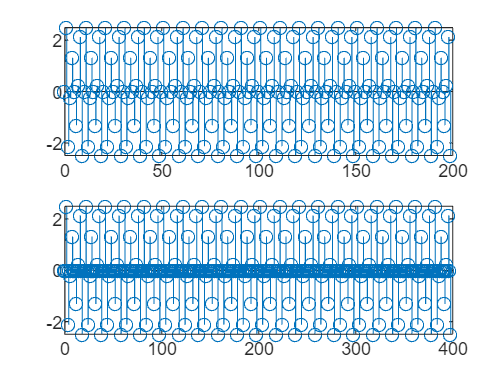

subplot(2,1,2)
stem(v,y)

clc
clear all
close all
t=0:0.01:10

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


x=zeros(1,length(t))

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x(find(t==0))=0

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


w=input('enter w: ')

w = 0.1000

a=[1 -2*cos(w) 1]

a =     1.0000   -1.9900    1.0000


b=[0 sin(w) 0]

b =          0    0.0998         0


y=zeros(1,length(t))

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x1=0

x1 = 0

x2=0

x2 = 0

y1=0

y1 = 0

y2=0

y2 = 0

for n=1:length(x)
    y(n)=b(1)*x(n)+b(2)*x1+b(3)*x2-a(2)*y1-a(3)*y2
    x2=x1
    x1=x(n)
    y2=y1
    y1=y(n)
end

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

x1 = 0

y2 = 0

y1 = 0

y = 1×1001
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = 0

subplot(2,1,1)
plot(t,x)
subplot(2,1,2)
plot(t,y)

